TrendTradingMainScript

Preparation

clear
    
tic

Read data

load TrendTrading.mat % IndexTT PriceTTFullRaw VolumeTTFullRaw
% IndexTT ;
% PriceTTFullRaw ;
% VolumesTTFullRaw = VolumeTTFullRaw ;

Clean data

% PricesTTFull = fillmissing (PriceTTFullRaw, "previous") ;
% PricesTTFull = fillmissing (PricesTTFull, "next") ;
% 
% VolumesTTFullRawVars = VolumesTTFullRaw.Variables ;
% VolumesTTFullRawVarsIdx = VolumesTTFullRawVars < 100';
% VolumesTTFullRawVars (VolumesTTFullRawVarsIdx) = NaN ;
% VolumesTTFullRaw.Variables = VolumesTTFullRawVars ;
% VolumesTTFull = fillmissing (VolumesTTFullRaw, "previous") ;


Split dataset into IST and OST

nRowFull = int64 (size (PricesTTFull,1)) ;
nRowISTproportion = 80/100 ;  % Proportion of dataset to be in Sample Dataset
nRowIST = int64(round(nRowISTproportion*nRowFull)) ;
nRowOST = round (nRowFull-nRowIST) ;

% IST dataset
StartIdx = 800 ;
PricesIST = (PricesTTFull (StartIdx :nRowIST, :)) ;
VolumesIST = (VolumesTTFull (StartIdx :nRowIST, :)) ;

% OST dataset
PricesOST = (PricesTTFull (nRowIST:end, :)) ;
VolumesOST = (VolumesTTFull (nRowIST:end, :)) ;


Backtest

% Backtest input

x = [10^3 10^9 10 -10 20 10^6 20 30 25 5 40 -8 4]

x = 	1.0e+09 *

    0.0000    1.0000    0.0000   -0.0000    0.0000    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000


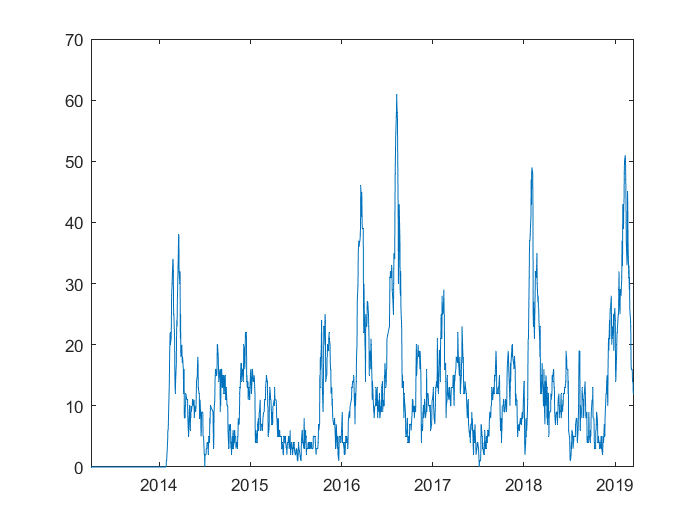

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                5.189     
    SharpeRatio             0.099616     
    Volatility              0.015413     
    AverageTurnover          0.10197     
    MaxTurnover              0.84615     
    AverageReturn          0.0015348     
    MaxDrawdown              0.29667     
    AverageBuyCost            50.412     
    AverageSellCost           67.073     


EndCumSumVar = -6.1890

TradingPeriod = 5.1370

CAGR = -0.4259

SharpeRatio = -1.5751

Sortino = -2.3875

Elapsed time is 8.645818 seconds.


SharpeRatio = -1.5751

% x = [10^3	10^9	100	80	200	10^15	10^15	200	80	200	200	80	200]

% lb = [10^3	10^6	1	-50	1	1	1	1	-50	1	1	-50	2] ;
% ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	200] ;

% LowSkipValTreshCorrection = x(1) ; 
% MinValue = x(2) ;
% MomContDays = x(3) ; 
% MomContRetTrheshold = x(4) ; 
% LowLiquidDays = x(5) ;
% LowLiquidThreshold = x(6) ;
% LiquidSurgThreshold = x(7) ;
% MomMainDays = x(8) ;
% MomMainRetThreshold = x(9) ;
% PostSignalBufferDays = x(10) ;
% StopLossLookbackWindSz = x(11) ;
% StopLossThreshold = x(12) ;
% RebalanceFreq = x(13) ;

% Call the function
SharpeRatio = TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) 

Optimize parameters in IST by using Genetic Algo

options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', ...
    false, "FunctionTolerance", 0.05, "MaxGenerations",20, 'MaxTime', 60*5)

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    MaxStallTime: Inf
                     MutationFcn: {@mutationgaus

options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping})

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                         PlotFcn: {@gaplotbestf  @gaplotstopping}
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    


FitnessFunction = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	200] ;

% ConstraintFunction = @nlconGA ;
IntCon = 1:nvars ;

[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [],IntCon, options )


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

     0

Elapsed time is 28.664355 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxD


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

     0


Sortino =

   NaN

Elapsed time is 29.127437 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn             


xSharpeGAOptimized = x ;


Optimize Sharpe Ratio by using Surrogate optim Algo

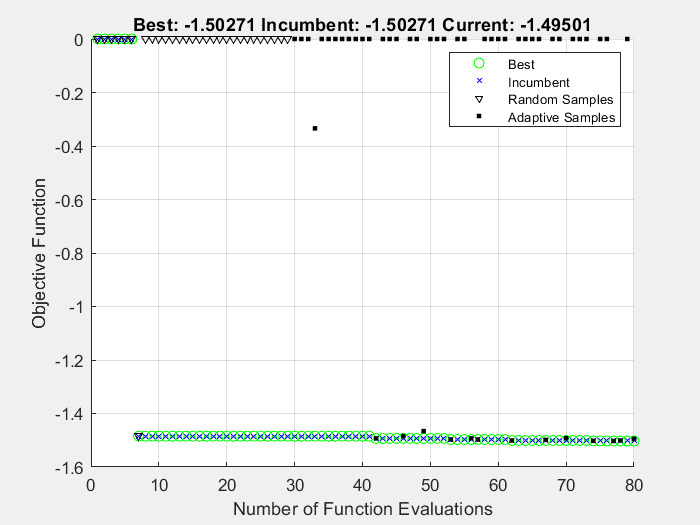

Optimization stopped by a plot function or output function.


%surrogateopt for expensive optim problems

NumFunctionEvaluations = 1000 ;
options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-6,'MaxFunctionEvaluations',NumFunctionEvaluations, 'UseParallel', true);

fun = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvar = 13 ;
lb = [10^3	10^6	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvar ;

[xSharpeSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options);


xSharpeSurOptimized = xSharpeSur 

xOptimizedsave = [xOptimized; xSharpeSur]


Optimize Sortino Ratio by using surrogateopt

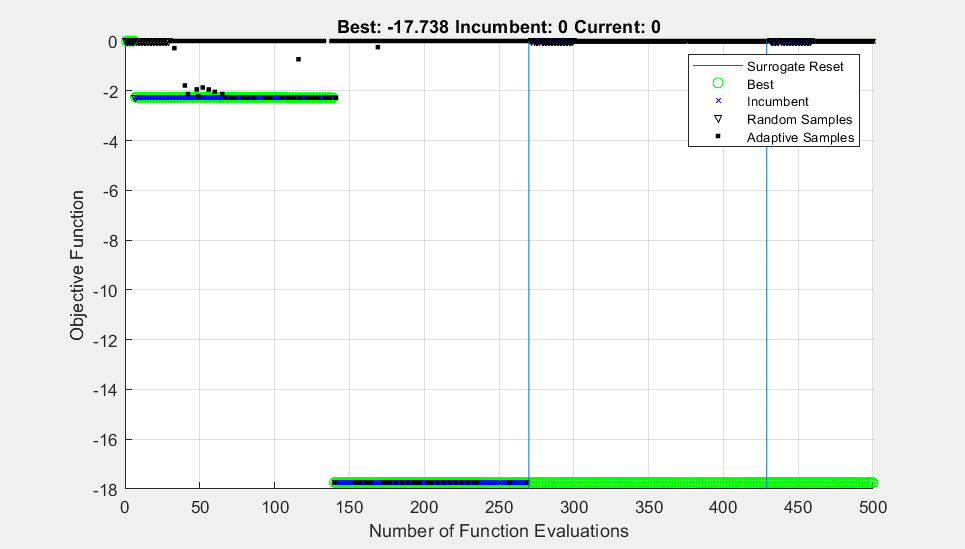

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


%surrogateopt for expensive optim problems

options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-6,'MaxFunctionEvaluations',500, 'UseParallel', true);

fun = @(x) TrendTradingFcnMultiVarSortino (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvars ;

[xSortinoSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options);


xSortinoSurOptimized = xSortinoSur ;



Pareto Search Multi-Objective Optim Sharpe Sortino CAGR

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = 0

Sortino = NaN

Elapsed time is 12.336697 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SortinoRatio = 0

Elapsed time is 12.500830 seconds.


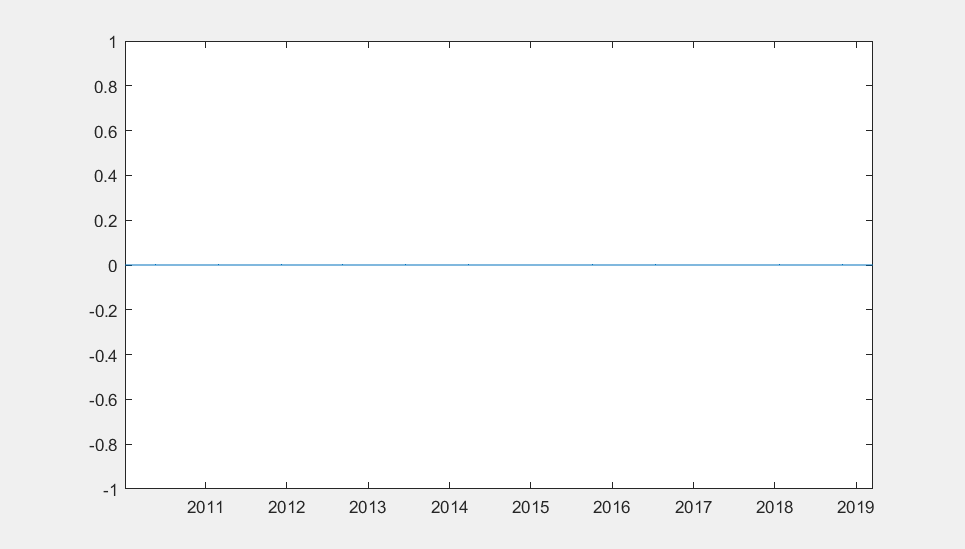

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = NaN

SortinoRatio = NaN

Elapsed time is 13.045303 seconds.


Unrecognized function or variable 'isna'.

Error in SharpeSortinoCAGRFitFcn (line 6)
SharpeRatio (isna (SharpeRatio)) = 0 ;

Error in TrendTradingMainScript (line 102)
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;

Error in 

optsp = optimoptions('paretosearch','UseParallel', true,'PlotFcn',{'psplotparetof' 'psplotparetox'});
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvar ;

% [xSsharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun,nvars,[],[],[],[],[],[],[],optsp)
% [xSsharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun,nvars,[],[],[],[],[],[],[],optsp);
[xSharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun, nvars, [], [], [], [], lb, ub, [], optsp)


xSharpeSorCAGRParetoOptimized = xSharpeSorCAGRPareto ;

Genetic Algo Multi-Objective Optim Sharpe Sortino CAGR

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = 0

Sortino = NaN

Elapsed time is 25.856827 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SortinoRatio = 0

Elapsed time is 26.548901 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = NaN

SortinoRatio = NaN

Elapsed time is 26.798486 seconds.


Unrecognized function or variable 'isna'.

Error in SharpeSortinoCAGRFitFcn (line 6)
SharpeRatio (isna (SharpeRatio)) = 0 ;

Error in TrendTradingMainScript (line 114)
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;

Error in 

options = optimoptions(@gamultiobj, 'PlotFcn',@gaplotpareto, 'UseParallel', true);
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvars ;

% [xSharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun,nvars,[],[],[],[],[],[],[],intcon,optsp)
% [xSharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun,nvars,[],[],[],[],[],[],[],optsp);
[xSharpeSorCAGRgamultiobj ,Fval,exitFlag,Output] = gamultiobj(fun, nvars, [], [], [], [], lb, ub, [], options)


xSharpeSorCAGRgamultiobjOptimized = xSharpeSorCAGRgamultiobj ;

Apply the parameters into IST - OST

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                3.0843    
    SharpeRatio               0.10732    
    Volatility              0.0064834    
    AverageTurnover          0.011409    
    MaxTurnover                   0.5    
    AverageReturn          0.00069562    
    MaxDrawdown               0.18746    
    AverageBuyCost             3.9335    
    AverageSellCost            5.1488    


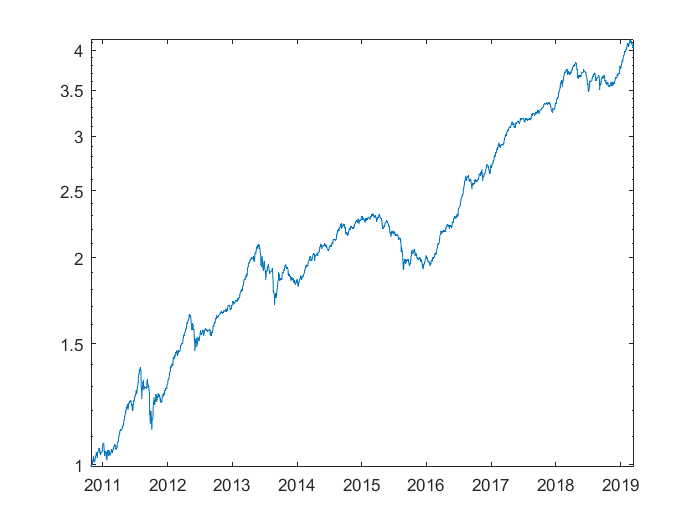

EndCumSumVar = -4.0843

TradingPeriod = 8.3973

CAGR = -0.1824

SharpeRatio = -1.6968

SortinoRatio = 1.8155

MaxDD = 0.1875

StartEndMaxDD = 2×1 datetime array
   01-Aug-2011
   04-Oct-2011


Elapsed time is 36.634106 seconds.


SharpeRatioOptimized = -1.6968

% xOptimized = xGAOptimized;
xOptimized = xSharpeSurOptimized ;
% xOptimized =  xSortinoSurOptimized ;

SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesIST, VolumesIST) 

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn               0.26975    
    SharpeRatio              0.077181    
    Volatility              0.0088136    
    AverageTurnover          0.016999    
    MaxTurnover                   0.5    
    AverageReturn          0.00067933    
    MaxDrawdown               0.28385    
    AverageBuyCost             2.6874    
    AverageSellCost             3.047    


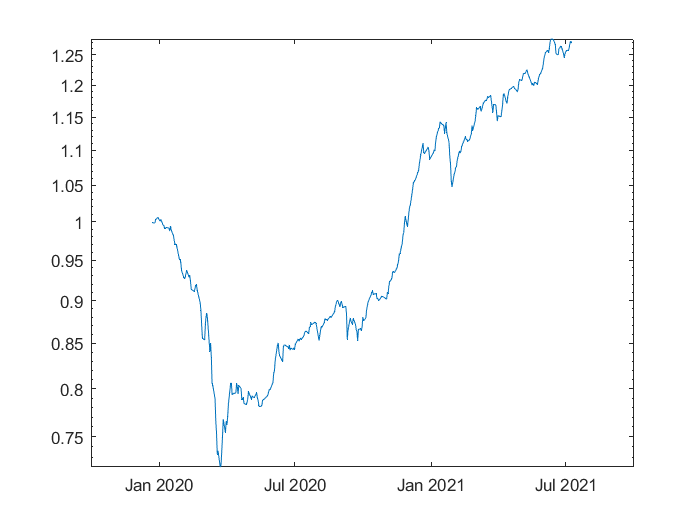

EndCumSumVar = -1.2698

TradingPeriod = 1.5410

CAGR = -0.1676

SharpeRatio = -1.2203

SortinoRatio = 1.5046

MaxDD = 0.2839

StartEndMaxDD = 2×1 datetime array
   30-Dec-2019
   23-Mar-2020


Elapsed time is 3.621650 seconds.


SharpeRatioOptimized = -1.2203

SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesOST, VolumesOST)

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                3.9875    
    SharpeRatio              0.093274    
    Volatility              0.0067261    
    AverageTurnover          0.012033    
    MaxTurnover                   0.5    
    AverageReturn          0.00062725    
    MaxDrawdown               0.32277    
    AverageBuyCost             4.8804    
    AverageSellCost             6.432    


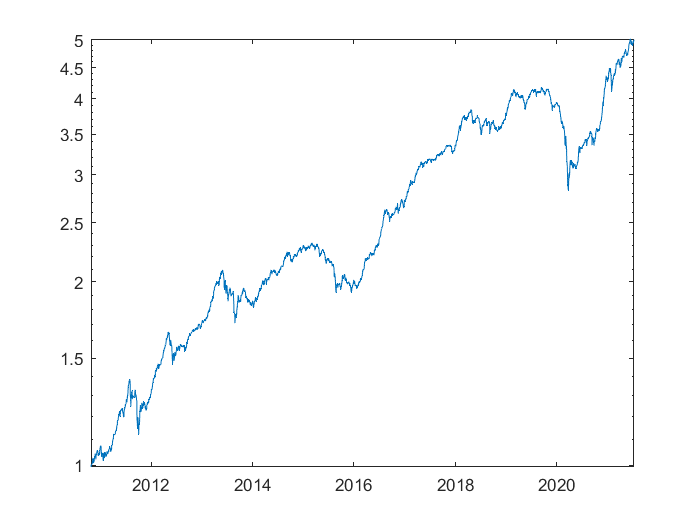

EndCumSumVar = -4.9875

TradingPeriod = 10.7096

CAGR = -0.1619

SharpeRatio = -1.4748

SortinoRatio = 1.6321

MaxDD = 0.3228

StartEndMaxDD = 2×1 datetime array
   12-Sep-2019
   23-Mar-2020


Elapsed time is 57.481403 seconds.


SharpeRatioOptimized = -1.4748

SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesTTFull, VolumesTTFull)

Examine OST

Save Variable


save ("TrendTrading.mat", 'PricesTTFull', "VolumesTTFull",  "xSharpeSurOptimized", 'xSortinoSurOptimized', 'xOptimized')

Closing

toc

Elapsed time is 1942.416299 seconds.
